ZIE MM MATLAB kurzus

# Alapok

## Témák:

- bevezetés

- környezet bemutatása

- fájl típusok bemutatása

- alapvető szintaktika

- értékadás

- műveleti operátorok

- alapvető adat típusok

clc; clear; close all;

## Bevezetés

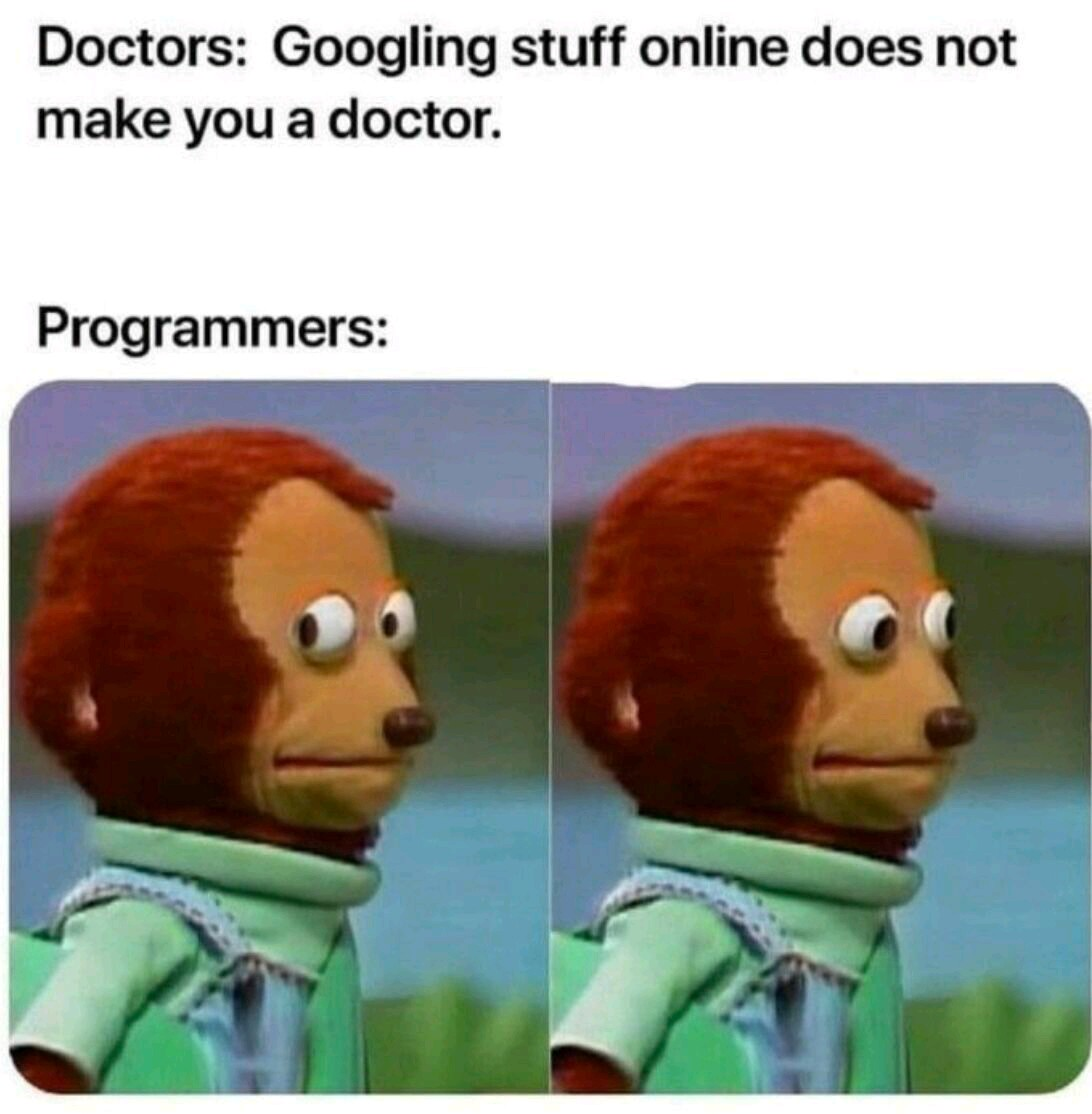

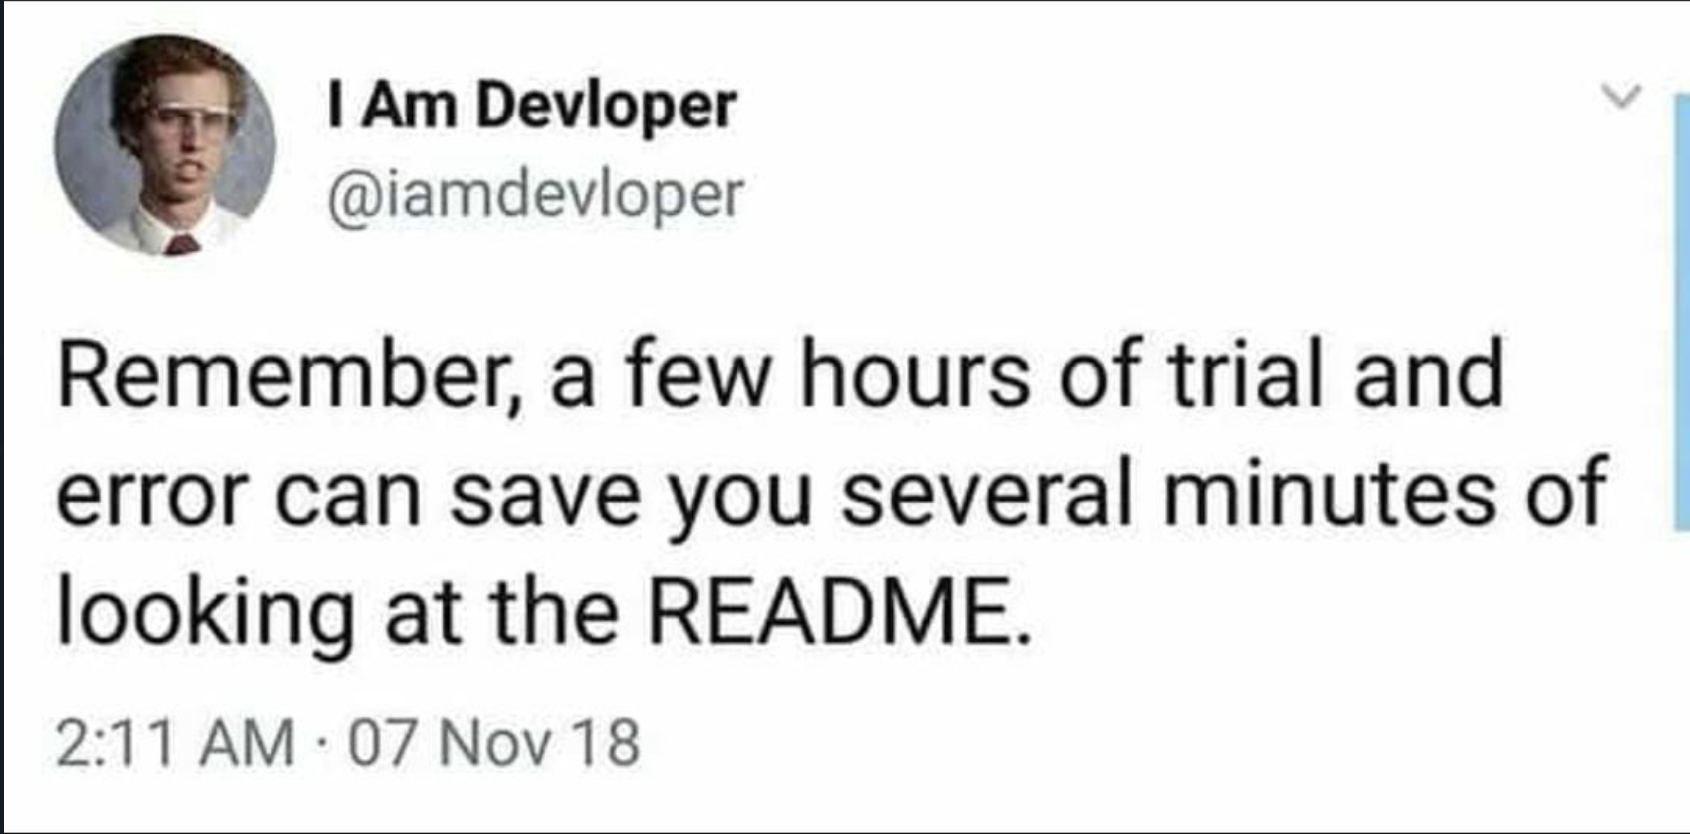

## Formázási lehetőségek

Szöveges blokk

% kód blokk

### Fontosabb gyors billentyűk

Általános:

- váltás blokk módok között: `Alt+Ent`

- szekció törés:` Ctrl+Alt+Ent`

- súgó: `F1` (**AJÁNLOTT HASZNÁLNI!)**

Szöveg szerkesztés:

- félkövér szöveg: `Ctrl+B` vagy` **szöveg**`

- dőlt szöveg: `Ctrl+I` vagy `*szöveg*`

- aláhúzott szöveg: `Ctrl+U`

- egyenlet beszúrása: `Ctrl+Shift+E` vagy `Ctrl+Shift+L` (LaTeX)

Kód szerkesztés:

- sorbehúzás: `Tab`

- sor visszahúzás: `Shift+Tab`

- sor komment: `Ctrl+R `vagy `% szöveg`

- sor komment törlése: `Ctrl+T`

- `futtatás: F5`

- Szekció futtatása: `Ctrl+Ent`

## Változók és típusok

Egyszerű értékadás:

a = 2;

Érték módosítás:

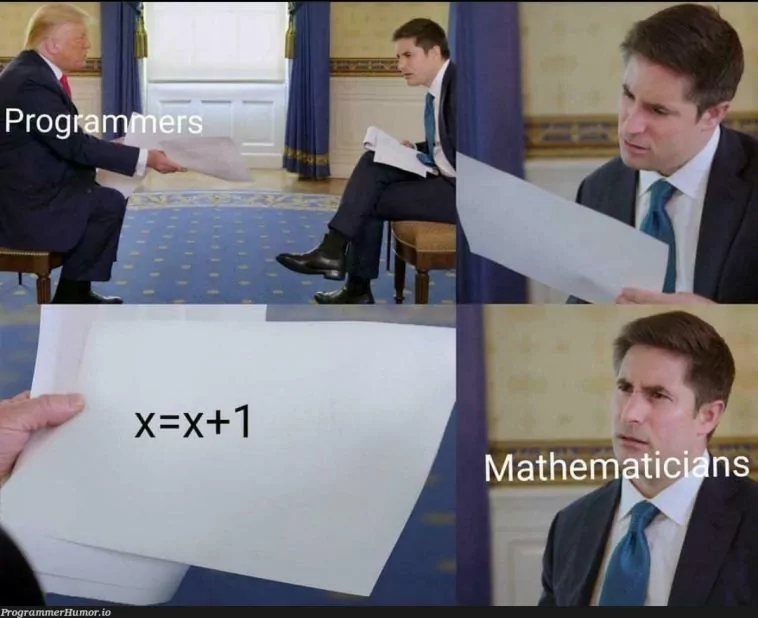

a = a + 1;

Kell pontos vessző?

b = 2
b = 3;

### Alap érték típusok

[https://www.mathworks.com/help/matlab/data-types.html](https://www.mathworks.com/help/matlab/data-types.html)

c = 2.5; % tizedestört (double)
d = 2; % egész szám (alapból tizedestörtként tárolva)
e = true; % logikai (logical/boolean)
f = "string"; % karakterlánc (string)
g = 'char'; % karaktervektor (char)

### Logikai értékek (boolean)

Lehetséges értékek:

true;
false;

Legtöbb program nyelvben a logikai értékek valójában számok. Tipikusan `false = 0` és `true` pedig minden más szám. MATLAB-ban csak és kizárólag `true = 1`.

false == 0
false == -1
true == 1
true == 2

Ugyanakkor itt is minden szám ami nem `0` "igazkásnak" számít, a `0` maga pedig "hamiskás".

logical(0)
logical(1)
logical(-1)
logical(inf)

### Szöveges értékek (strings)

[https://www.mathworks.com/help/matlab/characters-and-strings.html](https://www.mathworks.com/help/matlab/characters-and-strings.html)

Általában programozási nyelvekben csak egy fajta szöveges típus létezik. Python nyelvben például csak a `string` típus definiált és idézőjel valamint aposztróf is használható a jelölésére. Ezzel szemben MATLAB megkülönböztet két egyedi szöveges típust is.

h = "sumting"; % idézőjel -> karakterlánc (string)
i = 'sumting'; % aposztróf -> karaktervektor (char)

A kettő egy és ugyan az?

h == i

Úgy néz ki, hogy igen. De...

h(1) == i(1) % mind két változó első eleme

Lássuk mi is történik:

h(1)
i(1)

A két típus sokszor nem felcserélhető. Más és más függvények és érvényes műveletek tartoznak hozzájuk.

### Tömbök (arrays)

A legtöbb alap adattípus csoportosítható tömbökbe. Számok esetén a leggyakoribb tömbök:

- sor vektor

- oszlop vektor

- mátrix

Sor vektor definiálása:

j = [1,2,3,4]
k = [1 2 3 4]

Oszlop vektor definiálása:

l = [1;2;3;4]

Mátrix definiálása:

m = [
    [1,2];
    [3,4]
]
n = [[1 2];[3 4]]
o = [1, 2; 3, 4]

## Operátorok

Az operatátoroknak vagy más néven műveleti jeleknek három fő csoportja van:

- matematikai

- relációs

- logikai

Az operátorok feldolgozását szabályozza a műveleti sorrend melyet érdemes észben tartan komplex kifejezések írásakor. (A műveleti sorrend programnyelvenként változhat, így minden nyelvnek meg kell tanulni a saját logikáját.)

A műveleti sorrend egyértelműsítésére érdemes zárójeleket használni.

### Matematikai

Skalár műveletek skalár eredményt adnak:

2 + 3 % összeadés
2 - 3 % kivonás
2 * 3 % szorzás
2 / 3 % osztás
2 ^ 3 % hatványozás
-(-2) % negálás

Tömb műveletek tömb vagy skalár eredményt adnak:

j' % transzponálás
-j % negálás
j + k % összeadás
j - k % kivonás
j' * k % mátrix szorzás
m ^ 2 % mátrix hatványozás
j .* k % elemenkénti szorzás
j ./ k % elemenkénti osztás
m .^ 2 % elemenkénti hatványozás

### Relációs

Relációs műveletek logikai eredményt adnak:

2 > 3 % nagyobb
2 < 3 % kisebb
2 >= 3 % nagyobb vagy egyenlő
2 <= 3 % kisebb vagy egyenlő
2 == 3 % egyenlő
2 ~= 3 % nem egyenlő

### Logikai

Logikai műveletek logikai eredményt adnak:

~true % logikai negálás
true & false % elemenkénti ÉS
true | false % elemenkénti VAGY

Lusta kiértékelés / rövidre zárás esetén az operátor jobb oldalán lévő kifejezés nem kerül kiértékelésra, ha az már nem tud változtatni a végleges eredményen.

Rövidre zárt ÉS esetén a jobb oldal csak akkor kerül kiértékelésre, ha a bal oldal IGAZ. (HAMIS bal oldal esetén a kifejezés végső értéke mindenképpen HAMIS a jobb oldaltól függetlenül is.)

true && true % rövidre zárt ÉS (short-circuit AND)

Rövidre zárt VAGY esetén a jobb oldal csak akkor kerül kiértékelésre, ha a bal oldal HAMIS. (IGAZ bal oldal esetén a kifejezés végső értéke mindenképpen IGAZ, a jobb oldaltól függetlenül is.)

false || true % rövidre zárt VAGY (short-circuit OR)